s = getgenbank('AC116386')

s = struct with fields:
                LocusName: 'AC116386'
      LocusSequenceLength: '185556'
     LocusNumberofStrands: ''
            LocusTopology: 'linear'
        LocusMoleculeType: 'DNA'
     LocusGenBankDivision: 'ROD'
    LocusModificationDate: '04-DEC-2004'
               Definition: 'Mus musculus chromosome 15, clone RP23-37B16, complete sequence.'
                Accession: 'AC116386'
                  Version: 'AC116386.9'
                       GI: ''
                  Project: []
                   DBLink: []
                 Keywords: 'HTG.'
                  Segment: []
                   Source: 'Mus musculus (house mouse)'
           SourceOrganism: [4×66 char]
                Reference: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
                  Comment: [13×58 char]
                 Features: [704×53 char]
                      CDS: []
                 Sequence: 'gaattcttagcacacatccaggaccaaggctccggttatgagattccctctctggctggtctcagtattttagccatgagaaagc


bases = basecount(s, 'Ambiguous', 'bundle') %checking for ambiguous symbols

bases = struct with fields:
            A: 53700
            C: 44469
            G: 42317
            T: 45070
    Ambiguous: 0


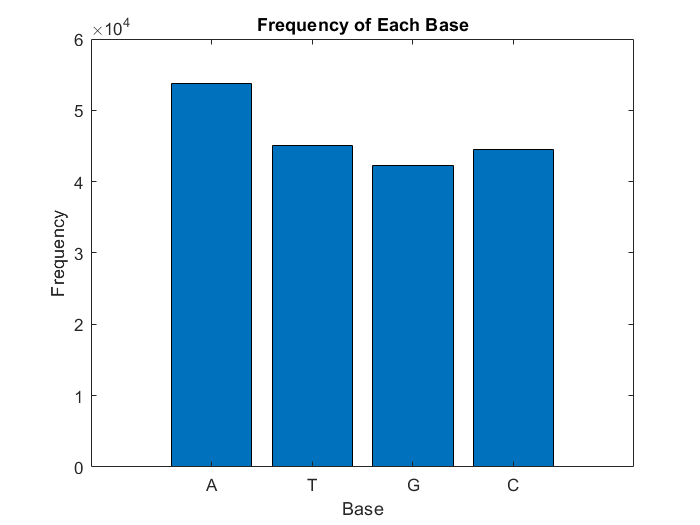

containsUracil = false; % making sure that there is no Uracil
for i = 1 : numel(s.Sequence)
    if(s.Sequence(i) == 'u')
        containsUracil = true;
    end
end
containsUracil;

types = {'A'; 'T'; 'G'; 'C'};
frequencies = [bases.A bases.T bases.G bases.C];
bases = bar(frequencies);
set(gca, 'xticklabel', types);
title('Frequency of Each Base');
ylabel('Frequency');
xlabel('Base');

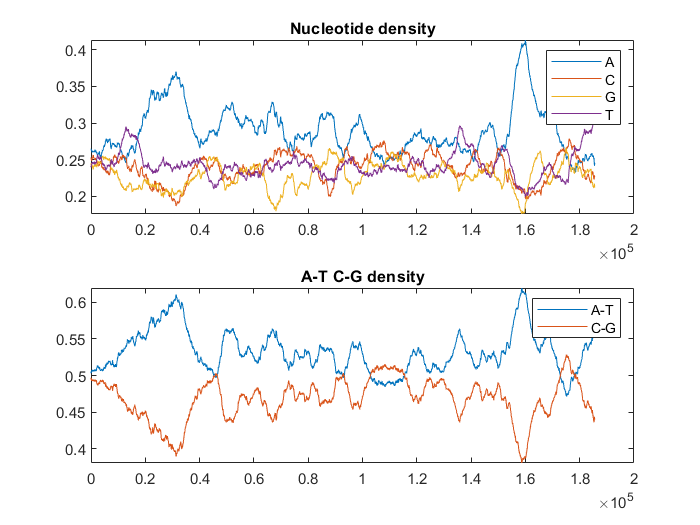

densities = struct with fields:
    A: [1×185556 double]
    C: [1×185556 double]
    G: [1×185556 double]
    T: [1×185556 double]



densities = ntdensity(s, 'Window', 6000)


dimerFrequencies = dimercount(s)

dimerFrequencies = struct with fields:
    AA: 15470
    AC: 11300
    AG: 15571
    AT: 11359
    CA: 16494
    CC: 12372
    CG: 1690
    CT: 13912
    GA: 12469
    GC: 9195
    GG: 11882
    GT: 8771
    TA: 9267
    TC: 11602
    TG: 13173
    TT: 11028


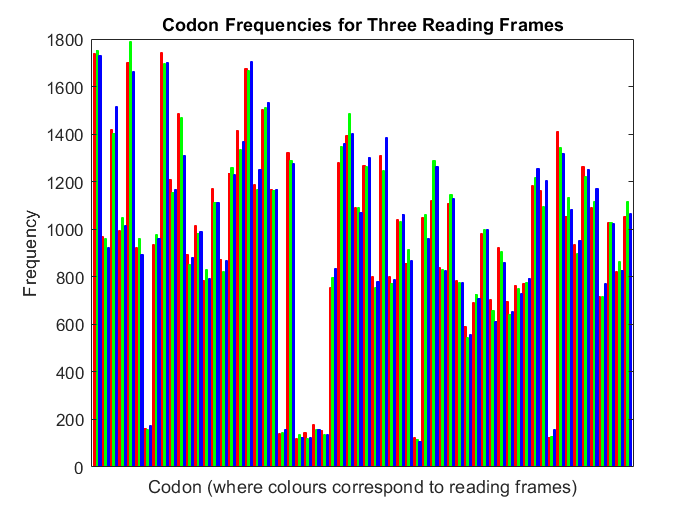


figure % to stop overlapping of graphs 
frequencies1 = codoncount(s, 'Frame', 1);
frequencies2 = codoncount(s, 'Frame', 2);
frequencies3 = codoncount(s, 'Frame', 3);
fields1 = fieldnames(frequencies1);
fields2 = fieldnames(frequencies2);
fields3 = fieldnames(frequencies3);
codons = zeros(1, numel(fields1)+numel(fields2)+numel(fields3));
j = 1;
for i = 1 : numel(fields1) % plotting for the first reading frame
    codons(j) = frequencies1.(fields1{i});
    first = bar(j, frequencies1.(fields1{i}));
    hold on;
    set(first, 'FaceColor', 'r');
    set(first, 'EdgeColor', 'r', 'LineWidth', 0.001);
    j = j+3;
end
j = 2;
for i = 1 : numel(fields2) %plotting for the second reading frame
    codons(j) = frequencies2.(fields2{i});
    second = bar(j, frequencies2.(fields2{i}));
    set(second, 'FaceColor', 'g');
    set(second, 'EdgeColor', 'g', 'LineWidth', 0.001);
    j = j+3;
end
j = 3;
for i = 1 : numel(fields3) %plotting for the third reading frame
    codons(j) = frequencies3.(fields3{i});
    third = bar(j, frequencies3.(fields3{i}));
    set(third, 'FaceColor', 'b');
    set(third, 'EdgeColor', 'b', 'LineWidth', 0.001);
    j = j+3;
end
hold off;
set(gca, 'XTick', []);
title('Codon Frequencies for Three Reading Frames');
ylabel('Frequency');
xlabel('Codon (where colours correspond to reading frames)');

maxVariance = 0;
maxVarianceIndex = 0;
j = 1;
while(j <= numel(codons)-2) %calculating maximum variance (and its position) and showing it in output
    currentVariance = var([codons(j) codons(j+1) codons(j+2)]);
    if(currentVariance > maxVariance)
        maxVariance = currentVariance;
        maxVarianceIndex = ((j-1)/3+1);
    end
    j = j+3;
end
maxVariance

maxVariance = 9.3773e+03

maxVarianceIndex

maxVarianceIndex = 11

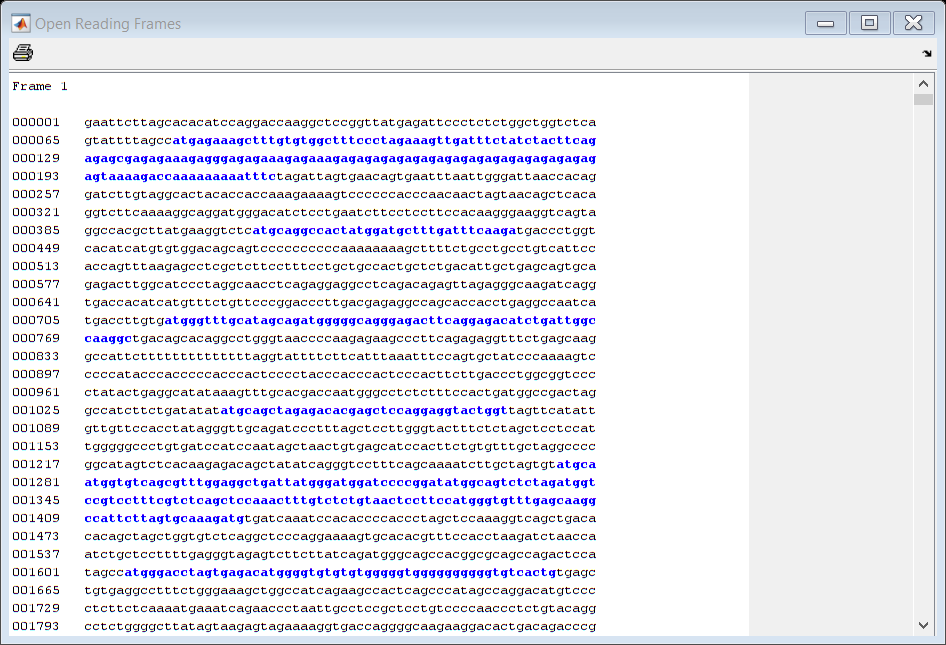


orfs = seqshoworfs(s.Sequence); % visualize open reading frames (although this is not used for counting)

uniqueORFs = strings(1, 5000); % large number because number of unique ORFs is unkown
orfFrequency = zeros(1, 5000); 
orfCounter = 0;
repeatCounter = 0;
i = 1;
k = 1;
while(i <= numel(s.Sequence)-5) % for first reading frame
    if(s.Sequence(i) == 'a' && s.Sequence(i+1) == 't' && s.Sequence(i+2) == 'g') 
        j = i+3;
        while(j <= numel(s.Sequence)-2)
            if((s.Sequence(j) == 't' && s.Sequence(j+1) == 'a' && s.Sequence(j+2) == 'a') || (s.Sequence(j) == 't' && s.Sequence(j+1) == 'a' && s.Sequence(j+2) == 'g') || (s.Sequence(j) == 't' && s.Sequence(j+1) == 'g' && s.Sequence(j+2) == 'a'))
                orfCounter = orfCounter+1;
                match = false;
                currentSubSequence = s.Sequence(i:j+2);
                while(match == false && orfFrequency(k) ~= 0)
                    if(currentSubSequence == uniqueORFs(k))
                        orfFrequency(k) = orfFrequency(k)+1;
                        repeatCounter = repeatCounter+1;
                        match = true;
                    end
                    k = k+1;
                end
                if(match == false)
                    orfFrequency(k) = orfFrequency(k)+1;
                    uniqueORFs(k) = currentSubSequence;
                end
                j = numel(s.Sequence);
            end
            j = j+3;
        end
    end
    i = i+3;
end
i = 2;
k = 1;
while(i <= numel(s.Sequence)-5) % for second reading frame
    if(s.Sequence(i) == 'a' && s.Sequence(i+1) == 't' && s.Sequence(i+2) == 'g') 
        j = i+3;
        while(j <= numel(s.Sequence)-2)
            if((s.Sequence(j) == 't' && s.Sequence(j+1) == 'a' && s.Sequence(j+2) == 'a') || (s.Sequence(j) == 't' && s.Sequence(j+1) == 'a' && s.Sequence(j+2) == 'g') || (s.Sequence(j) == 't' && s.Sequence(j+1) == 'g' && s.Sequence(j+2) == 'a'))
                orfCounter = orfCounter+1;
                match = false;
                currentSubSequence = s.Sequence(i:j+2);
                while(match == false && orfFrequency(k) ~= 0)
                    if(currentSubSequence == uniqueORFs(k))
                        orfFrequency(k) = orfFrequency(k)+1;
                        repeatCounter = repeatCounter+1;
                        match = true;
                    end
                    k = k+1;
                end
                if(match == false)
                    orfFrequency(k) = orfFrequency(k)+1;
                    uniqueORFs(k) = currentSubSequence;
                end
                j = numel(s.Sequence);
            end
            j = j+3;
        end
    end
    i = i+3;
end
i = 3;
k = 1;
while(i <= numel(s.Sequence)-5) %for third reading frame
    if(s.Sequence(i) == 'a' && s.Sequence(i+1) == 't' && s.Sequence(i+2) == 'g') 
        j = i+3;
        while(j <= numel(s.Sequence)-2)
            if((s.Sequence(j) == 't' && s.Sequence(j+1) == 'a' && s.Sequence(j+2) == 'a') || (s.Sequence(j) == 't' && s.Sequence(j+1) == 'a' && s.Sequence(j+2) == 'g') || (s.Sequence(j) == 't' && s.Sequence(j+1) == 'g' && s.Sequence(j+2) == 'a'))
                orfCounter = orfCounter+1;
                match = false;
                currentSubSequence = s.Sequence(i:j+2);
                while(match == false && orfFrequency(k) ~= 0)
                    if(currentSubSequence == uniqueORFs(k))
                        orfFrequency(k) = orfFrequency(k)+1;
                        repeatCounter = repeatCounter+1;
                        match = true;
                    end
                    k = k+1;
                end
                if(match == false)
                    uniqueORFs(k) = currentSubSequence;
                    orfFrequency(k) = orfFrequency(k)+1;
                end
                j = numel(s.Sequence);
            end
            j = j+3;
        end
    end
    i = i+3;
end
orfCounter % number of open reading frames

orfCounter = 3395

repeatCounter % number of repetitions

repeatCounter = 9

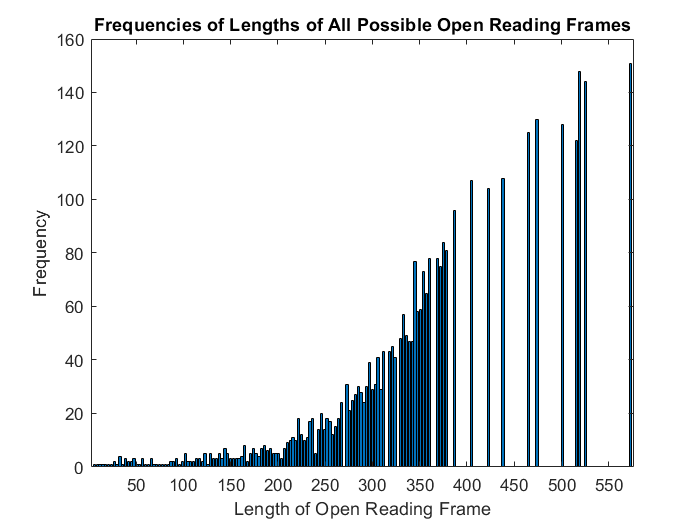


refinedLength = orfCounter-repeatCounter; % cutting unnecissary zeros
refinedORFs = strings(1, refinedLength); % cutting unnecissary zeros
refinedFrequencies = zeros(1, refinedLength); % cutting unnecissary zeros
orfLengths = zeros(1, refinedLength);
for i = 1 : refinedLength
    refinedORFs(i) = uniqueORFs(i); % cutting unnecissary zeros
end
[~,sortingIndex] = sort(cellfun(@length,refinedORFs),'descend');
refinedORFs = refinedORFs(sortingIndex); % sorting from lowest to highest
for i = 1 : refinedLength
    refinedFrequencies(i) = orfFrequency(i);
    orfLengths(i) = strlength(refinedORFs(i));
end
ignoreIndexes = zeros(1, numel(orfLengths)); % specifying where the repeats are so that those indexes can be ignored
ignoreCounter = 1;
lengthFrequencies = zeros(1, numel(orfLengths));
shift = 0; % how many spaces are skipped to ignoring indexes
i = 1;
while(i <= numel(orfLengths)) % create the actual array to be graphed (FOR X AND Y AXIS!)
    ignore = false;
    for k = 1 : numel(ignoreIndexes)
        if(i == ignoreIndexes(k))
            ignore = true;
        end
    end
    if(ignore == true)
        shift = shift+1;
    else
        lengthFrequencies(i-shift) = lengthFrequencies(i-shift)+1;
        for j = i+1 : numel(lengthFrequencies)
            if(orfLengths(i) == orfLengths(j))
                lengthFrequencies(i-shift) = lengthFrequencies(i-shift)+1;
                ignoreIndexes(ignoreCounter) = j;
                ignoreCounter = ignoreCounter+1;
            end
        end
    end
    i = i+1;
end
ignoreCounter = ignoreCounter-1;
i = 1;
stop = false;
while(stop == false)
    if(lengthFrequencies(i) == 0)
        stop = true;
    end
    i = i+1;
end
i = i-2;
finalFrequencies = zeros(1, i);
for i = 1 : numel(finalFrequencies)
    finalFrequencies(i) = lengthFrequencies(i);
end
orfLengths = flip(orfLengths);
finalLengths = zeros(1, numel(finalFrequencies));
finalLengths(1) = orfLengths(1);
i = 2;
index = 2;
while(i <= numel(orfLengths))
    if(orfLengths(i) ~= finalLengths(index-1))
        finalLengths(index) = orfLengths(i);
        index = index+1;
    end
    i = i+1;
end
bar(finalLengths, finalFrequencies); %plotting
title('Frequencies of Lengths of All Possible Open Reading Frames');
ylabel('Frequency');
xlabel('Length of Open Reading Frame');